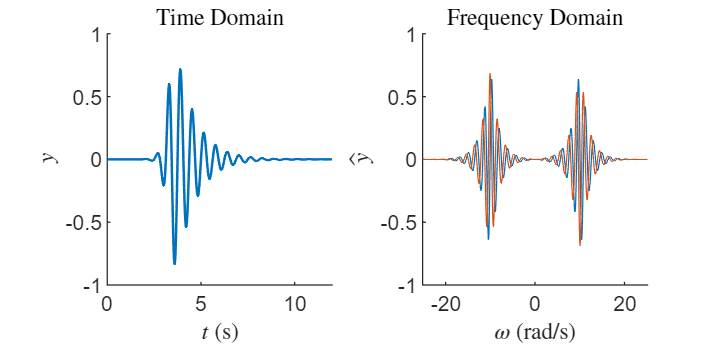

L = 5.9; % The domain half-width
N = 55; % The number of Fourier modes to use in the series
 
fourierEstimateSech(L,N) % Helper function that creates the plots

function fourierEstimateSech(L,Nmodes)
    % This function creates a figure that illustrates
    % how the Fourier series only models a finite domain

    % Parameters
    tf = 100;
    ts = 2;
    tmid = 6;
    sigma = 0.2;
    freq = 1.6;
    Nt = 5000;
    
    % Domain and function
    ylims = [-1,1];
    tlims = [0,tf];
    freqLims = [-4,4];
    t = linspace(tlims(1),tlims(2),Nt);
    sechValue = 2./(exp((0.2*t-ts)/sigma) + exp(-(t-ts)/sigma));
    y = sin(2*pi*freq*t).*sechValue/1200;

    g = y;
    Fs = Nt/tlims(2);
    G = fft(g);
    Gscaled = G*1/Fs;
    Gshift = fftshift(Gscaled);
    N = numel(g);
    omega = 2*pi*Fs/N*(-N/2:N/2-1);


    % Create the figure and subplots
    colors = lines(4);
    figure("OuterPosition",[1,1,800,400])
    subplot(1,2,1)
    plot(t,y,"Linewidth",1)
%     patch([tc(1),   tc(1),   tc(end), tc(end),  tc(1)],...
%           [ylims(1),ylims(2),ylims(2),ylims(1), ylims(1)],[0.3,0.3,0.3],"FaceAlpha",0.1,EdgeAlpha=0.75)
    ylim(ylims)
    xlim([0,12])
    ylabel("$y$","Interpreter","latex")
    xlabel("$t$ (s)","Interpreter","latex")
    title("Time Domain","Interpreter","latex")
    box off

    subplot(1,2,2)
    plot(omega,real(Gshift),"Color",colors(1,:))
    hold on
    plot(omega,imag(Gshift),"Color",colors(2,:))
    hold off
    xlim(freqLims*2*pi)
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{y}$","Interpreter","latex")
    title("Frequency Domain","Interpreter","latex")
    box off

end

